# AI and Robotics LAb-1 (LABSHEET 1 & 2)

## NikhilSanjay(BL.EN.U4CSE23239)

R = rot2(45)

R =     0.5253   -0.8509
    0.8509    0.5253


R = rot2(45,'deg')

R =     0.7071   -0.7071
    0.7071    0.7071


R = rotx(45),roty(45),rotz(45)

R =     1.0000         0         0
         0    0.5253   -0.8509
         0    0.8509    0.5253


ans =     0.5253         0    0.8509
         0    1.0000         0
   -0.8509         0    0.5253


ans =     0.5253   -0.8509         0
    0.8509    0.5253         0
         0         0    1.0000


R=rotx(45,'deg')

R =     1.0000         0         0
         0    0.7071   -0.7071
         0    0.7071    0.7071


clf;
clear all;
R = rot2(45,'deg')

R =     0.7071   -0.7071
    0.7071    0.7071


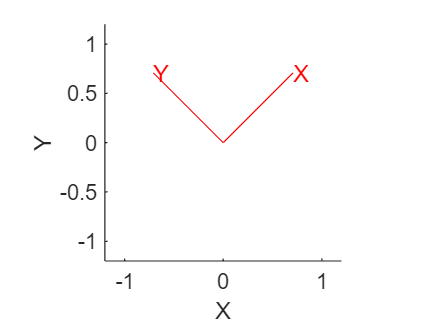

H =   Transform with properties:

    Children: [4×1 Graphics]
     Visible: on
     HitTest: on
      Matrix: [4×4 double]

  Show all properties


H=trplot2(R,'color','r')

clf;
clear all;
R = rotx(45,'deg')

R =     1.0000         0         0
         0    0.7071   -0.7071
         0    0.7071    0.7071


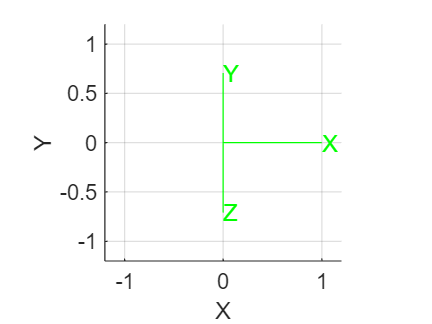

trplot(R,'color','g')

T = transl2(2,3)

T =      1     0     2
     0     1     3
     0     0     1


H = transl2(4,9) * trot2(70,'deg') 

H =     0.3420   -0.9397    4.0000
    0.9397    0.3420    9.0000
         0         0    1.0000


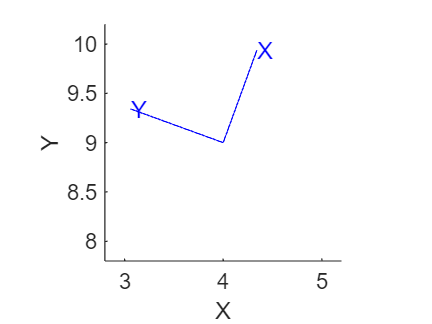

clf;
trplot2(H)

clf;
axis([-4 4 -4 4 -4 4]);     
view(3);                  
grid on;
hold on;
H1 = transl(1,2,3)*troty(45,'deg')

H1 =     0.7071         0    0.7071    1.0000
         0    1.0000         0    2.0000
   -0.7071         0    0.7071    3.0000
         0         0         0    1.0000


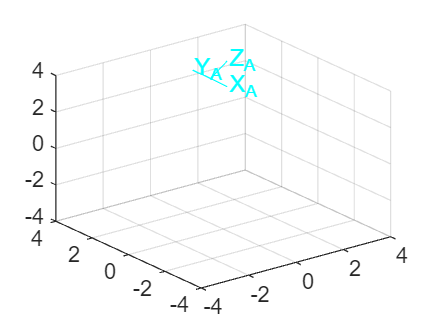

trplot(H1, 'frame', 'A', 'color', 'c');

clf;
axis([-4 4 -4 4 -4 4]);     
view(3); 
grid on
H = transl2(4,9)*trot2(70,'deg')

H =     0.3420   -0.9397    4.0000
    0.9397    0.3420    9.0000
         0         0    1.0000


H1=eye(3)

H1 =      1     0     0
     0     1     0
     0     0     1


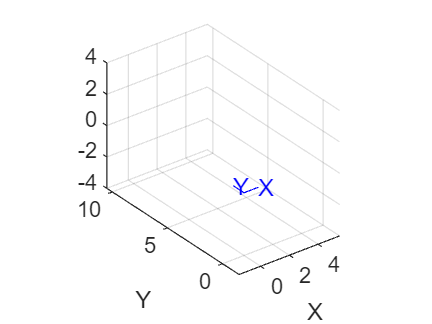

tranimate2(H,H1)

## Practice Questions

theta = 45;                      
R = trotz(theta, 'deg');        
R = R(1:3, 1:3);                 
RT_R = R' * R;                   
inverse_R = inv(R);              
det_R = det(R);                  

disp('R'' * R =');

R' * R =


disp(RT_R)

     1     0     0
     0     1     0
     0     0     1




disp('inv(R) =');

inv(R) =


disp(inverse_R)

    0.7071    0.7071         0
   -0.7071    0.7071         0
         0         0    1.0000




disp('R'' =');

R' =


disp(R')

    0.7071    0.7071         0
   -0.7071    0.7071         0
         0         0    1.0000




disp('det(R) =');

det(R) =


disp(det_R)

     1



X=rotx(90);

X =     1.0000         0         0
         0   -0.4481   -0.8940
         0    0.8940   -0.4481


XY=X*roty(0);

XY =     1.0000         0         0
         0   -0.4481   -0.8940
         0    0.8940   -0.4481


XYX = XY*rotx(90);

XYX =     1.0000         0         0
         0   -0.5985    0.8012
         0   -0.8012   -0.5985


compareX = rotx(180)

compareX =     1.0000         0         0
         0   -0.5985    0.8012
         0   -0.8012   -0.5985


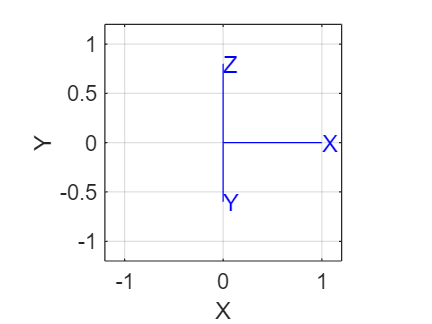


trplot(XYX)

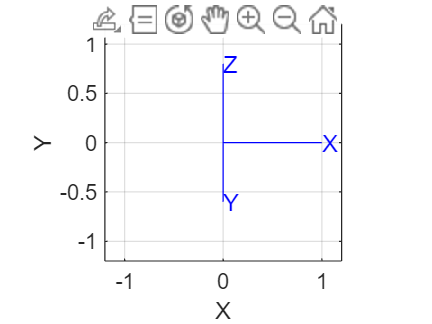

trplot(rotx(180))

## LAB SHEET  - 2

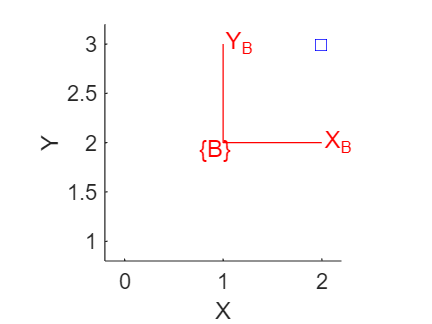

clear all;
clf;
clc;
B = transl2(1,2);
Ap=[2;3];
trplot2(B,'frame','B','color','r')
hold on
plot_point(Ap)

Pb = inv(B)*[Ap;1]

Pb =      1
     1
     1


h2e(Pb)

ans =      1
     1


Pb = h2e(inv(B)*e2h(Ap))

Pb =      1
     1


syms theta
R = rot2(theta)

$$R = \left(\begin{array}{cc} \cos\left(\theta \right) & -\sin\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

simplify(R*R)

$$ans = \left(\begin{array}{cc} \cos\left(2\,\theta \right) & -\sin\left(2\,\theta \right)\\ \sin\left(2\,\theta \right) & \cos\left(2\,\theta \right) \end{array}\right)$$

R = eul2r(0.1,0.2,0.3)

R =     0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


EU = eul2r(0.1,-0.2,0.3)

EU =     0.9021   -0.3836   -0.1977
    0.3875    0.9216   -0.0198
    0.1898   -0.0587    0.9801


EU2 = eul2tr(EU)

EU2 =     0.9021   -0.3836    0.1977         0
    0.3875    0.9216    0.0198         0
   -0.1898    0.0587    0.9801         0
         0         0         0    1.0000


R1 = eul2r(EU)

R1 =     0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


## PRACTICE QUESTION

H = eul2r(1,4,8)

H =    -0.7811    0.4718   -0.4089
    0.6146    0.4656   -0.6368
   -0.1101   -0.7487   -0.6536


H = H* rotx(45,'deg')*roty(70,'deg')*rotz(30,'deg')

H =     0.2977   -0.1205   -0.9470
    0.7558   -0.5762    0.3109
   -0.5832   -0.8084   -0.0805


eulerAngles = eul2tr(H)

eulerAngles = eulerAngles(:,:,1) =

    0.7924    0.5990   -0.1149         0
   -0.6059    0.7948   -0.0353         0
    0.0702    0.0976    0.9928         0
         0         0         0    1.0000


eulerAngles(:,:,2) =

    0.3711   -0.8397   -0.3965         0
    0.7702    0.5169   -0.3737         0
    0.5187   -0.1667    0.8385         0
         0         0         0    1.0000


eulerAngles(:,:,3) =

    0.5304    0.5952   -0.6036         0
   -0.4462    0.8014    0.3982         0
    0.7208    0.0581    0.6907         0
         0         0         0    1.0000


AngelVector = tr2angvec(H)

AngelVector = 2.3179

RPY = tr2rpy(H)

RPY =    -1.6700    0.6226    1.1956
